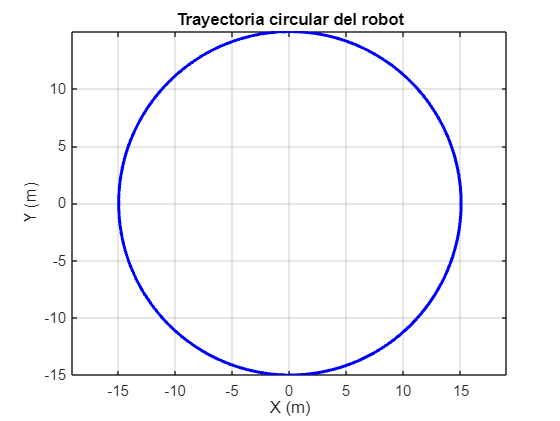

clear; 
clc; 
close all;

%% Parámetros del robot
r = 0.05;      % radio de rueda (m)
L = 0.18;      % distancia entre ruedas (m)
R = 15;       % radio de trayectoria circular (m)
u = 1;        % velocidad lineal deseada (m/s)
w = u / R;    % velocidad angular necesaria (rad/s)

%% Tiempo de simulación
ts = 0.1;         % tiempo de muestreo (s) se puede cambiar a 1 segundo
T_total = 130;     % tiempo total (s) 40 para una parte
N = T_total / ts; % número de muestras
t = 0:ts:T_total-ts;

%% Cálculo de velocidades de las ruedas
wr = (2*u + w*L) / (2*r); % constante
wl = (2*u - w*L) / (2*r); % constante

wr_vec = wr * ones(1, N);
wl_vec = wl * ones(1, N);

%% Cálculo de u y w en cada paso (solo para tabla)
u_vec = (r/2) * (wr_vec + wl_vec);
w_vec = (r/L) * (wr_vec - wl_vec);

%% Inicialización de variables
x = zeros(1, N+1);
y = zeros(1, N+1);
theta = zeros(1, N+1);  % en radianes

x(1) = 0;
y(1) = -R;  % Posición inicial en el borde del círculo
theta(1) = 0;

%% Simulación de la trayectoria
for k = 1:N
    theta(k+1) = theta(k) + w_vec(k) * ts;
    
    x(k+1) = x(k) + u_vec(k) * cos(theta(k)) * ts;
    y(k+1) = y(k) + u_vec(k) * sin(theta(k)) * ts;
end

theta_deg = rad2deg(theta);

%% Visualización en 2D
figure;
plot(x, y, 'b', 'LineWidth', 2); grid on; axis equal;
xlabel('X (m)');
ylabel('Y (m)');
title('Trayectoria circular del robot');


%% Mostrar tabla de resultados
x_trim = x(1:end-1);
y_trim = y(1:end-1);
theta_trim = theta_deg(1:end-1);

T = table(t', wr_vec', wl_vec', u_vec', w_vec', x_trim', y_trim', theta_trim', ...
    'VariableNames', {'t', 'wr', 'wl', 'u', 'w', 'x', 'y', 'theta_deg'});

disp('Tabla de resultados:');

Tabla de resultados:


disp(T);

      t       wr       wl      u       w            x            y        theta_deg
    _____    _____    _____    _    ________    _________    _________    _________

        0    20.12    19.88    1    0.066667            0          -15           0 
      0.1    20.12    19.88    1    0.066667          0.1          -15     0.38197 
      0.2    20.12    19.88    1    0.066667          0.2      -14.999     0.76394 
      0.3    20.12    19.88    1    0.066667      0.29999      -14.998      1.1459 
      0.4    20.12    19.88    1    0.066667      0.39997      -14.996      1.5279 
      0.5    20.12    19.88    1    0.066667      0.49993      -14.993      1.9099 
      0.6    20.12    19.88    1    0.066667      0.599

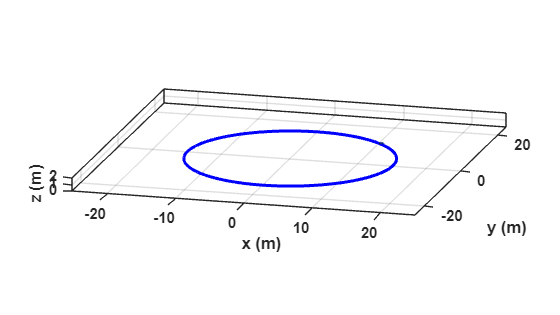






%% Animación en 3D de la trayectoria circular

% Crear escena 3D
scene = figure;
set(scene, 'Color', 'white');
set(gca, 'FontWeight', 'bold');
sizeScreen = get(0, 'ScreenSize');
set(scene, 'position', sizeScreen);
camlight('headlight');
axis equal;
grid on; box on;
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
view([15 15]);
axis([-25 25 -25 25 0 2]);

% Graficar robot en posición inicial
scale = 4;           % escala del robot
MobileRobot_5;       % función que define el robot
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
H2 = plot3(x(1), y(1), 0, 'b', 'LineWidth', 2);

% Bucle de animación
step = 1;
for k = 1:step:N
    delete(H1);
    delete(H2);
    
    % Graficar robot y su trayectoria
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    H2 = plot3(x(1:k), y(1:k), zeros(1, k), 'b', 'LineWidth', 2);
    
    pause(ts);  % control del tiempo de simulación
end